# **demo05 of writeMesh**

**Node sets at the boundary and interface when writing inp file**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Overview

By default, function printInp2d will automatically search and export node sets at the boundary and at the interface of 2d mesh. These node sets can be used to defined boundary condition.

- Node sets at the boundary (global minimum and maximum). For example, node set 'Set-Xmin-B' means nodes at global x minimum location and they belong to phase B.

- Node sets at the interface between different material phases. For example, node set 'Set-Interf-BC' means nodes at the interface between phase B and phase C.

We can also choose not to automatically search and export node sets. We can use parameter 'opt.tf_printMaxMinNode' and 'opt.opt.tf_printInterfNode' to achieve this. 

- When we set 'opt.tf_printMaxMinNode = 0;', the exported inp file will not include node sets at global minimum and maximum.

- When we set 'opt.tf_printInterfNode = 0;', the exported inp file will not include node sets at the interface between different material phases.

Function printInp2d can define customized node sets. We can use parameter 'opt.user_nodeSet' to achieve this.

For example, 

            opt.user_nodeSet{1} = { 'my-1', [2 5 8] };

            opt.user_nodeSet{2} = { 'my-2', [36 23 56 80] };

We will show examples in this demo.

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_2.mat"

load("mesh_data_2.mat")

We will see 3 variables: vert, ele, tnum

size(vert)

ans =     61     2


size(ele)

ans =     96     3


size(tnum)

ans =     96     1


## Plot mesh

Use function plotMeshes to plot mesh.

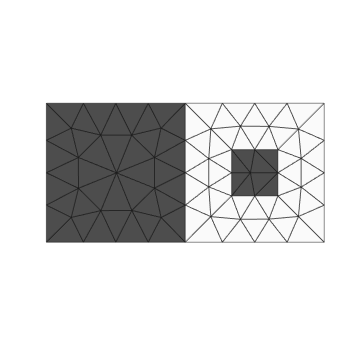

plotMeshes(vert,ele,tnum);

## Export as inp file (by default)

We use function printInp2d to write 2d mesh into inp file.

By default, function printInp2d will automatically search and export node sets at the boundary and at the interface of 2d mesh. 

ele_type = 'CPS3';
precision = 8;
file_name = 'test_1.inp';

printInp2d( vert, ele, tnum, ele_type, precision, file_name );

printInp2d Done! Check the inp file!


## Do not automatically search and export node sets

We can use parameter 'opt.tf_printMaxMinNode' and 'opt.opt.tf_printInterfNode' to achieve this. When we set them to 0, the exported inp file will not include node sets at the boundary and at the interface.

ele_type = 'CPS3';
precision = 8;
file_name = 'test_2.inp';

opt = [];
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

printInp2d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp2d Done! Check the inp file!


## Define customized node sets 

We can use parameter 'opt.user_nodeSet' to achieve this. 

For example, 'opt.user_nodeSet{1} = { 'my-1', [2 3 4] };' means defining node 2, 3, 4 as a node set. The name of the node set is 'Set-my-1'.

ele_type = 'CPS3';
precision = 8;
file_name = 'test_3.inp';

opt = [];
opt.user_nodeSet{1} = { 'my-1', [2 3 4] };
opt.user_nodeSet{2} = { 'my-2', [10 15 20 25] };

printInp2d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp2d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo